# Sistema de control levitación magnética

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)
% Funcion de transferencia resultante C*Y*B
G = C * Y * B

% calculos test de controlabilidad
AB = A*B
A2B = A^2 *B 
Mc = [B AB A2B]
det(Mc)
% calculos test de observabilidad
CA = C*A
CA2 = C *A^2
Mo = [C ;CA ;CA2]
det(Mo)

% sustituyendo los datos del trabajo proporcionado por Teppa

equiA = subs(A, [c X3 X1 m R L], [0.0001 7 0.01 0.05 1 0.01])
equiB = subs(B, L, 0.01)
equiG = vpa(expand(subs(G, [c X3 X1 m R L], [0.0001 7 0.01 0.05 1 0.01])),2)

% Forma canonica controlable


In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$G = \frac{2\,X_{1}\,X_{3}\,c}{\left({X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2}\right)\,\left(R+L\,s\right)}$$

$$AB = \left(\begin{array}{c} 0\\ -\frac{2\,X_{3}\,c}{L\,X_{1}\,m}\\ -\frac{R}{L^{2}} \end{array}\right)$$

$$A2B = \left(\begin{array}{c} -\frac{2\,X_{3}\,c}{L\,X_{1}\,m}\\ \frac{2\,R\,X_{3}\,c}{L^{2}\,X_{1}\,m}\\ \frac{R^{2}}{L^{3}} \end{array}\right)$$

$$Mc = \left(\begin{array}{ccc} 0 & 0 & -\frac{2\,X_{3}\,c}{L\,X_{1}\,m}\\ 0 & -\frac{2\,X_{3}\,c}{L\,X_{1}\,m} & \frac{2\,R\,X_{3}\,c}{L^{2}\,X_{1}\,m}\\ \frac{1}{L} & -\frac{R}{L^{2}} & \frac{R^{2}}{L^{3}} \end{array}\right)$$

$$ans = -\frac{4\,{X_{3}}^{2}\,c^{2}}{L^{3}\,{X_{1}}^{2}\,m^{2}}$$

$$CA = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

$$CA2 = \left(\begin{array}{ccc} \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m} \end{array}\right)$$

$$Mo = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m} \end{array}\right)$$

$$ans = -\frac{2\,X_{3}\,c}{X_{1}\,m}$$

$$equiA = \left(\begin{array}{ccc} 0 & 1 & 0\\ 980 & 0 & -\frac{14}{5}\\ 0 & 0 & -100 \end{array}\right)$$

$$equiB = \left(\begin{array}{c} 0\\ 0\\ 100 \end{array}\right)$$

$$equiG = \frac{1.4e-5}{-5.0e-8\,s^{3}-5.0e-6\,s^{2}+4.9e-5\,s+4.9e-3}$$

## LMI

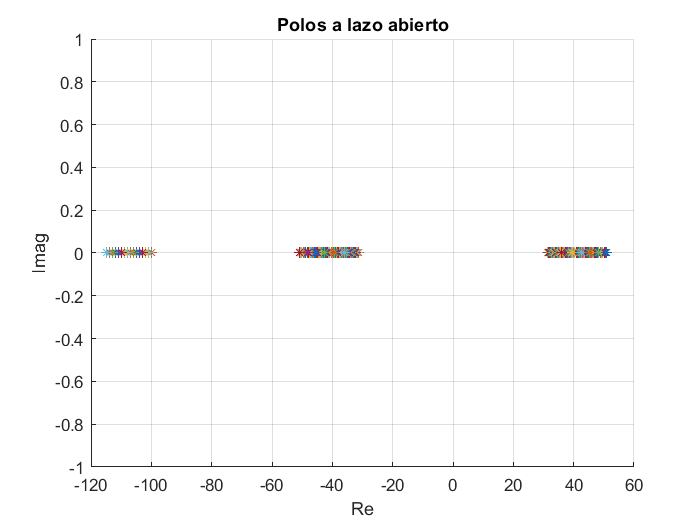



% Definimos los valores variables de la matriz 

% Tomando como valores variables la masa y la resistencia y valores fijos
% la constante "c", la inductancia "L" y la tensión "V"

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2);
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)));
%q3 A(3,3)
q3 = -R/L;
%q4 B(3,1)
q4 = 1/L;

% Sustituimos los valores por defecto 

q1 = subs(q1, [c V g], [0.0001, 7, 9.81]);
q2 = subs(q2, [c V g], [0.0001, 7, 9.81]);
q3 = subs(q3, L, 0.01);
q4 = subs(q4, L, 0.01);


% Localizamos los polos para el caso donde R varia entre 1 y 1.5, la masa
% entre 0.05Kg y 0.1Kg

figure
for r=1:0.01:1.15
   q3f = subs(q3, R, r);
   q2f = subs(q2, R, r);
    for M=0.05:0.01:0.1
        q1f = subs(q1, [R m], [r, M]);
        A=[0 1 0; q1f 0 q2f; 0 0 q3f];
        p=eig(A);
        hold on
        plot(real(p(1)),imag(p(1)),'*')
        plot(real(p(2)),imag(p(2)),'*')
        plot(real(p(3)), imag(p(3)), '*')
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off

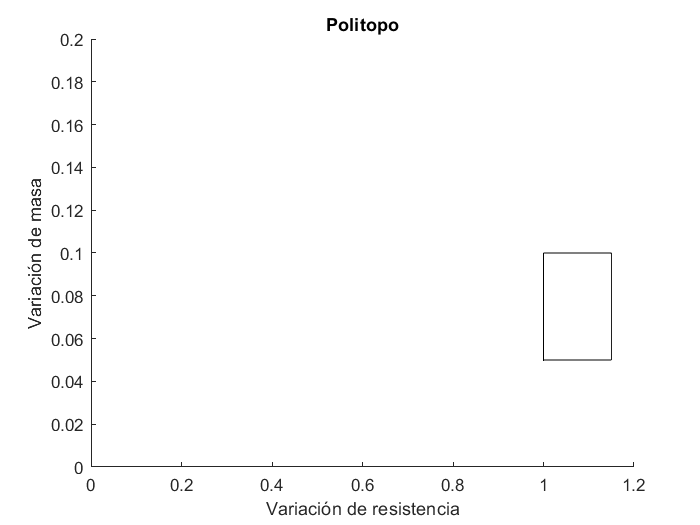


% Dibujamos el politopo 
figure
rectangle('Position', [1 0.05 0.15 0.05])
title('Politopo')
xlabel('Variación de resistencia')
ylabel('Variación de masa')
axis([0 1.20 0 0.2])



% Creamos la desigualdad lineal matricial 



